# Excersise 3

Here the objective is to move the end-effector of a painting robot tangent to a plane with a particular painting (curve on it). The end effector must keep the same orientation w.r.t the canvas and follow the trajectory.

import plotFrame.*;

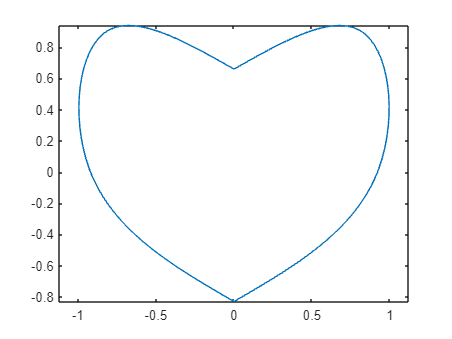

clear all;

alpha = pi/18; % degrees

points = [0 .82 .92 0 0 -.92 -.82 0; .66 .9 0 ...
-.83 -.83 0 .9 .66];

[curve, t] = fnplt(cscvn(points));

plot(curve(1, :), curve(2, :));
axis equal;

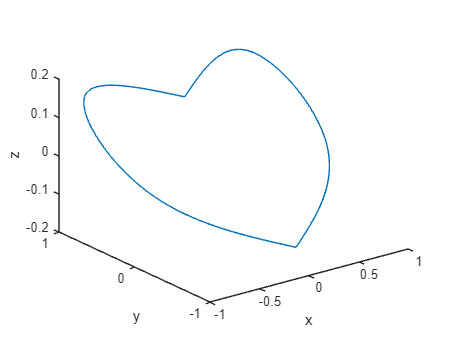

curve3D = [curve; zeros(1, length(curve))];
rotCurve3D = rotx(rad2deg(alpha))*curve3D;

plot3(rotCurve3D(1, :), rotCurve3D(2, :), rotCurve3D(3, :));
xlabel("x");
ylabel("y");
zlabel("z");